part 1

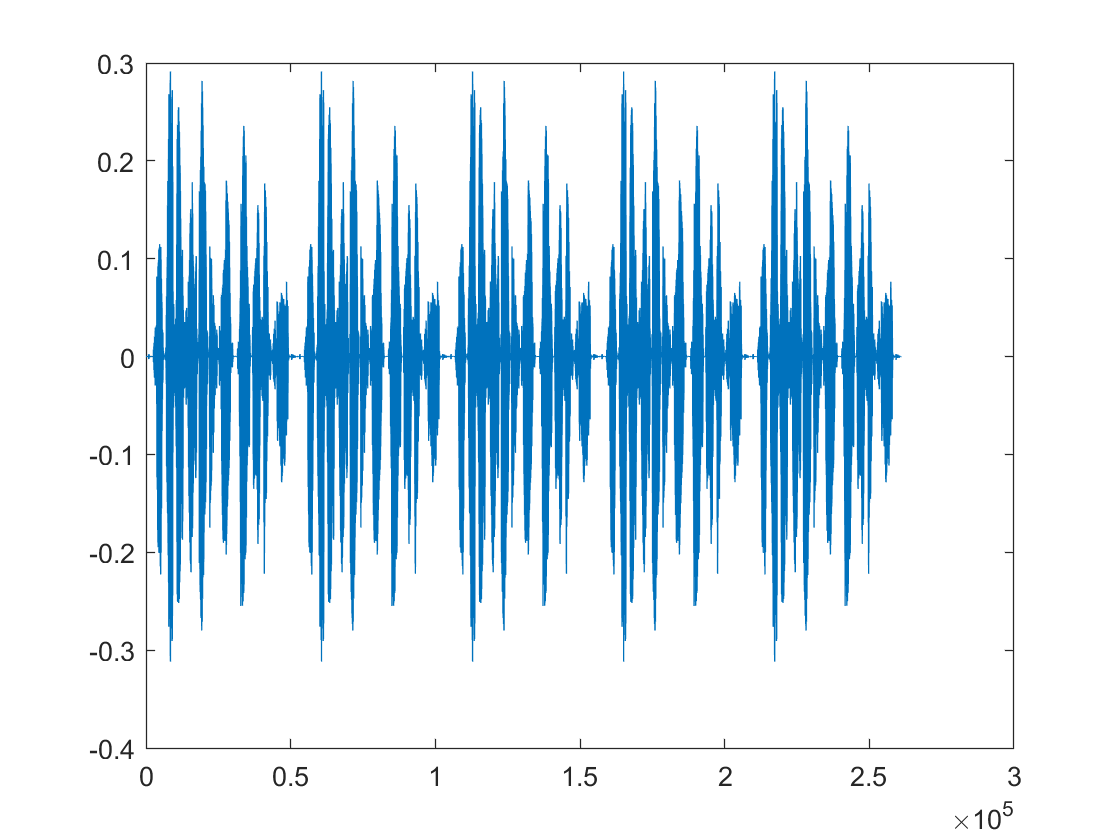

[Y1,fs1] = audioread('C_01_01.wav');
[Y2,fs2] = audioread('C_01_02.wav');
sig=Y1';
sound(Y1,fs1);
sig=repmat(sig,1,5);
figure;
plot(sig);

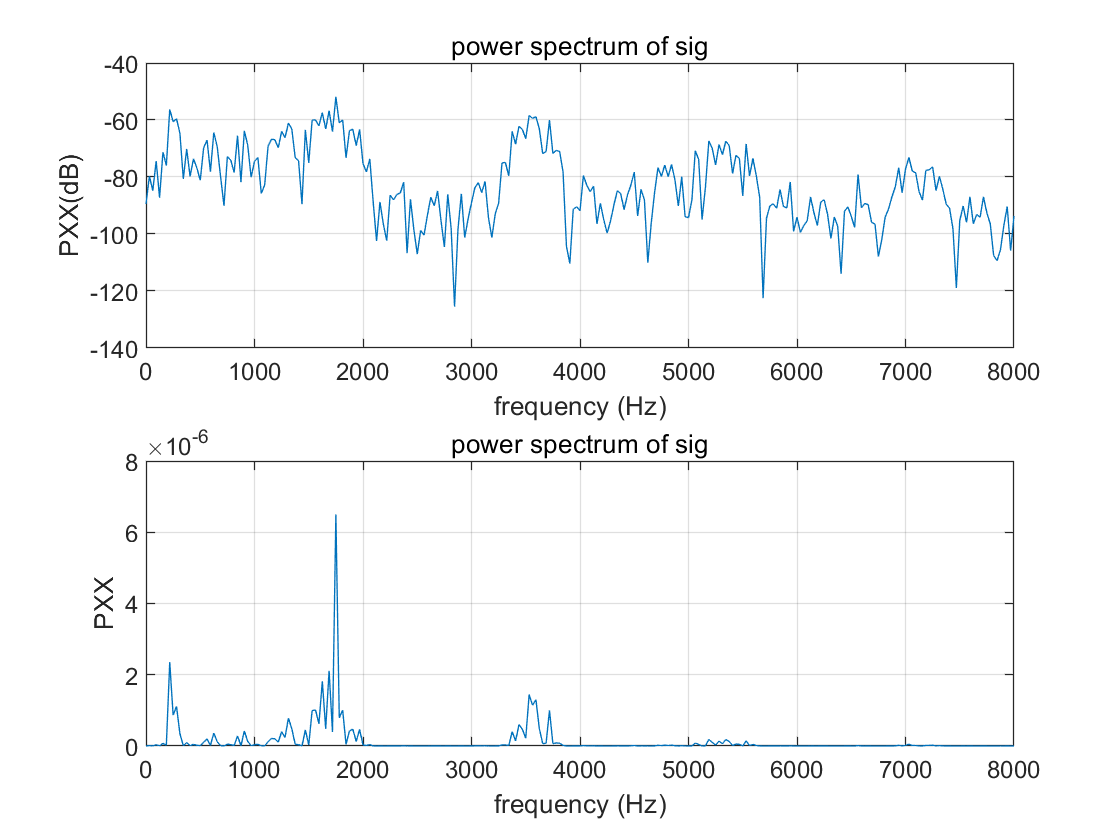


[Pxx,w] = periodogram(sig,[],512,fs1);
figure;
subplot(211);
plot(w,10*log10(Pxx));
grid on;

title("power spectrum of sig");
xlabel("frequency (Hz)");
ylabel("PXX(dB)")
subplot(212);
plot(w,(Pxx));
grid on;

title("power spectrum of sig");
xlabel("frequency (Hz)");
ylabel("PXX");

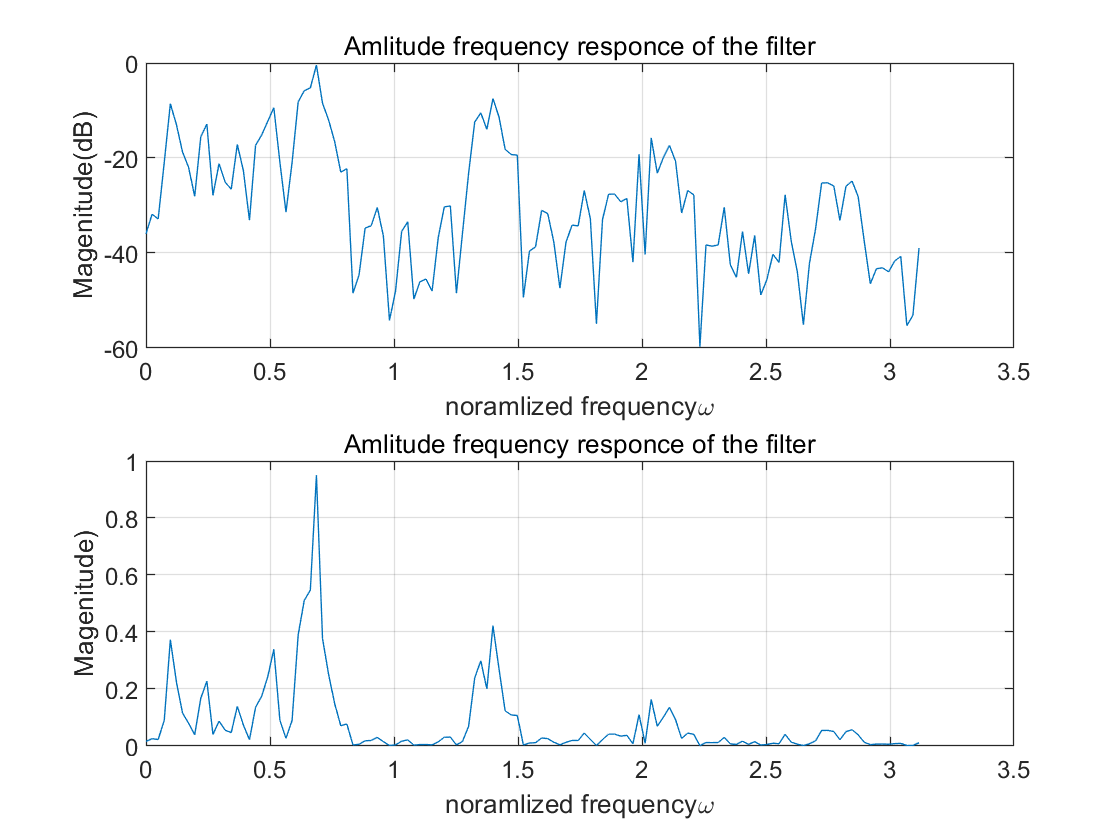


b=fir2(3000,w/(fs1/2),sqrt(Pxx/max(Pxx)));
[h,wh]=freqz(b,1,128);

figure;
subplot(211); 
plot(wh,20*log10(abs(h)));
grid on;
title("Amlitude frequency responce of the filter");
xlabel("noramlized frequency\omega");
ylabel("Magenitude(dB)");
subplot(212); 
plot(wh,abs(h));
grid on;
title("Amlitude frequency responce of the filter");
xlabel("noramlized frequency\omega");
ylabel("Magenitude)");

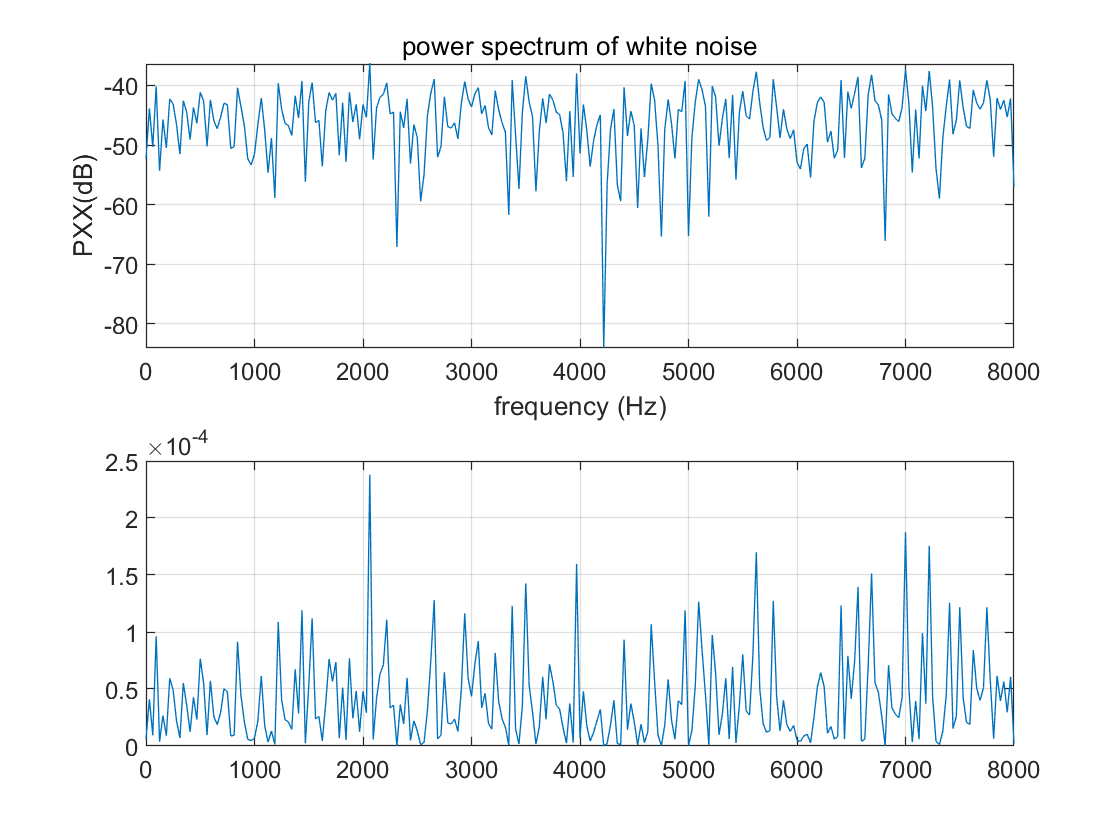

%noise
N=length(sig);
noise = 1-2*rand(1,N);
[Pxx,w] = periodogram(noise,[],512,fs1);
figure;
subplot(211);
plot(w,10*log10(Pxx));
grid on;

title("power spectrum of white noise");
xlabel("frequency (Hz)");
ylabel("PXX(dB)")
subplot(212);
plot(w,(Pxx));
grid on;

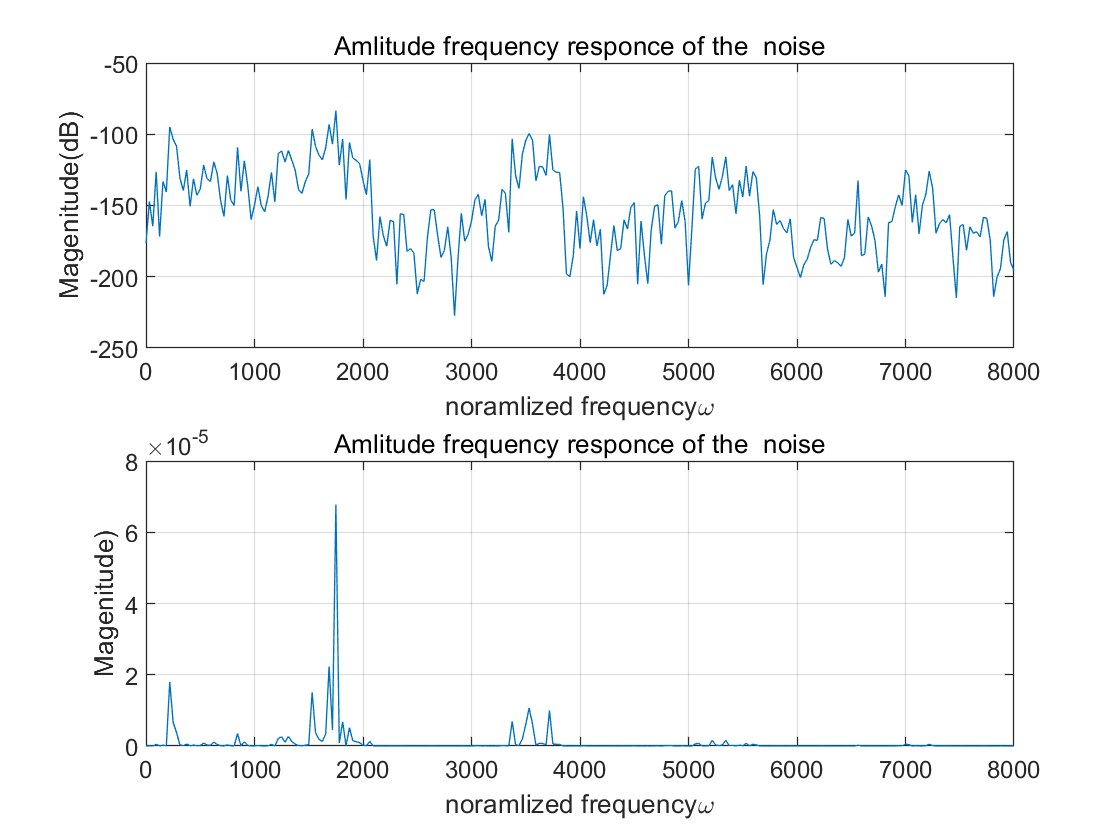


 
SSN=filter(b,1,noise);
[Pxx,w] = periodogram(SSN,[],512,fs1);
figure;
subplot(211); 
plot(w,20*log10(abs(Pxx)));
grid on;
title("Amlitude frequency responce of the  noise");
xlabel("noramlized frequency\omega");
ylabel("Magenitude(dB)");
subplot(212); 
plot(w,abs(Pxx));
grid on;
title("Amlitude frequency responce of the  noise");
xlabel("noramlized frequency\omega");
ylabel("Magenitude)");

part2

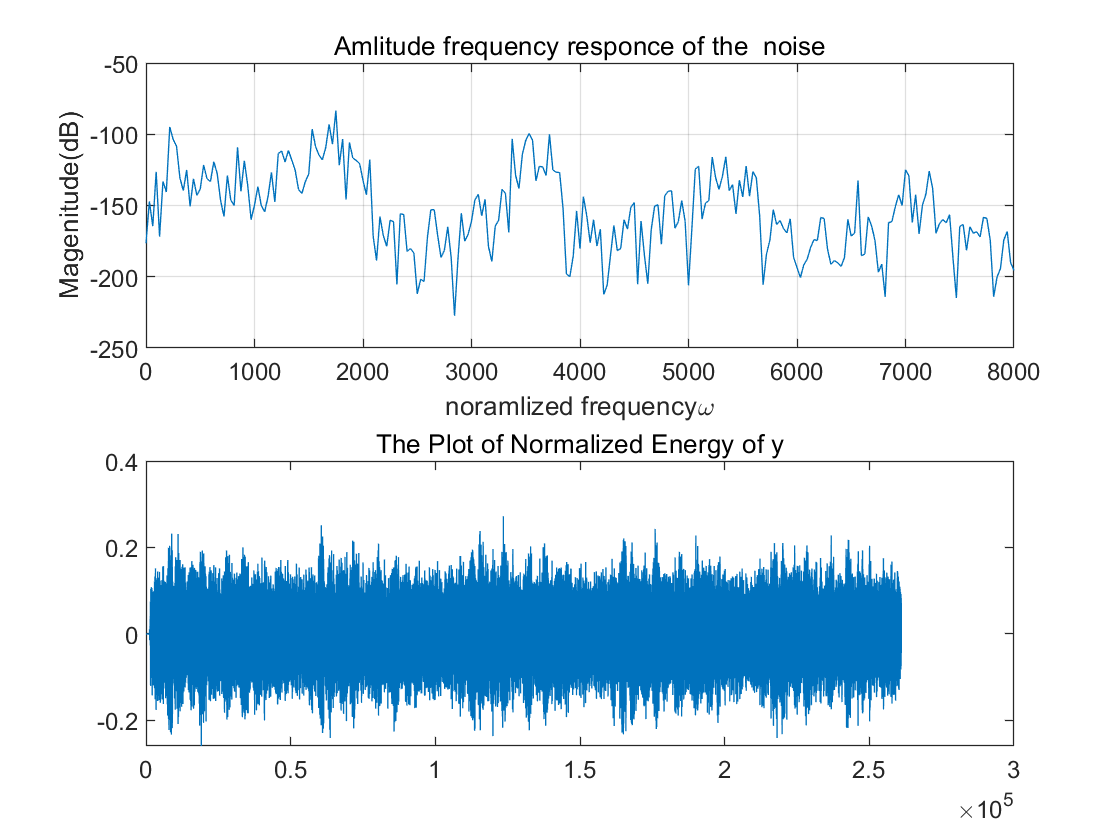

requiredSNR=-5;
normratio=10^(requiredSNR/20);
SSN=SSN*norm(sig)/norm(SSN)/normratio;
SNR=20*log10(norm(sig)/norm(SSN));
y=sig+SSN;
y = y*norm(sig)/norm(y);
plot(y)
title('The Plot of Normalized Energy of y');